load('C:\Users\Asus\Desktop\data_A')

    x=data_noise(1:1000,1:11);
    y=data_noise(1:1000,12);
    rng('default');
    cv = cvpartition(size(x,1),'HoldOut',0.3);
    idx = cv.test;
% Separate to training and test data
   x_train = x(~idx,:);
   x_test  = x(idx,:);
   y_train = y(~idx,:);
   y_test  = y(idx,:); 

% mse_values = [];
% regressor_subset = ones(size(x_train, 2), size(x_train, 2)); % Assuming x_train has size N-by-P
% max_iterations = size(x_train, 2);
% regressors_each_iteration = cell(1, max_iterations);
% 
% for i = 1:max_iterations
%     mdl = fitlm(x_train(:, logical(regressor_subset(:, i))), y_train);
%    
%     y_pred = predict(mdl, x_train(:, logical(regressor_subset(:, i))));
%     
%     mse_values(i) = mean((y_train - y_pred).^2);
%     
%     [~, max_p_value_idx] = max(mdl.Coefficients.pValue(2:end));
%     
%     regressor_subset(max_p_value_idx, i+1) = 0;
%     selected_regressors = find(regressor_subset(:, i));
%     regressors_each_iteration{i} = selected_regressors;
%     regressor_subset(max_p_value_idx, i+1:end) = 0;
% end
% 
% 
% [min_mse, min_mse_idx] = min(mse_values);
% best_regressor_subset = regressor_subset(:, min_mse_idx);
% 
% figure;
% plot(1:max_iterations, mse_values, 'bo-');
% xlabel('Iteration');
% ylabel('Model Error (MSE)');
% title('Model Error vs. Backward Elimination Iterations');
% 
% 
% fprintf('Regressors for each Iteration:\n');
% for i = 1:max_iterations
%     selected_regressors = regressors_each_iteration{i};
%     fprintf('Iteration %d: ', i);
%     for j = 1:length(selected_regressors)
%         fprintf('%d ', selected_regressors(j));
%     end
%     fprintf('\n');
% end
% 
% final_model = fitlm(x_train(:, logical(best_regressor_subset)), y_train);
% y_pred_test = predict(final_model, x_test);
% mse_test = mean((y_test - y_pred_test).^2);


mse_values = [];
regressor_subset = ones(size(x_train, 2), size(x_train, 2)); % Assuming x_train has size N-by-P
max_iterations = size(x_train, 2);

regressors_each_iteration = cell(1, max_iterations);

for i = 1:max_iterations
    X = x_train(:, logical(regressor_subset(:, i)));
    theta = (X' * X) \ (X' * y_train);
    y_pred = X * theta;

    mse_values(i) = mean((y_train - y_pred).^2);
    [~, max_p_value_idx] = max(abs(theta));
    regressor_subset(max_p_value_idx, i+1) = 0;
 
    selected_regressors = find(regressor_subset(:, i));
    regressors_each_iteration{i} = selected_regressors;

    regressor_subset(max_p_value_idx, i+1:end) = 0;
end

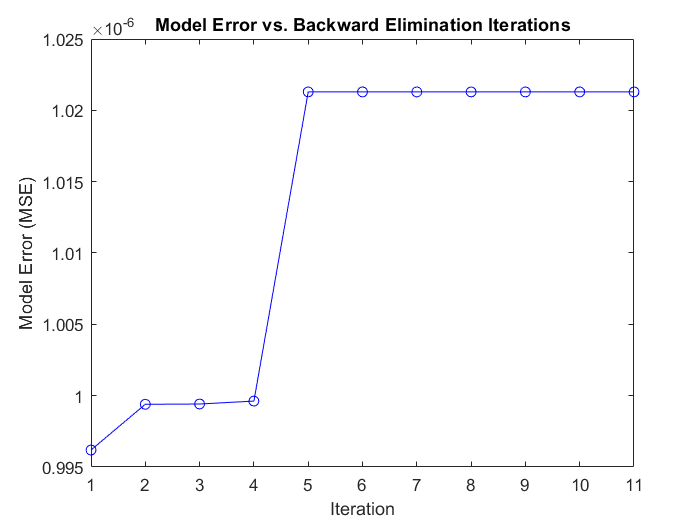


[min_mse, min_mse_idx] = min(mse_values);

best_regressor_subset = regressor_subset(:, min_mse_idx);

figure;
plot(1:max_iterations, mse_values, 'bo-');
xlabel('Iteration');
ylabel('Model Error (MSE)');
title('Model Error vs. Backward Elimination Iterations');


fprintf('Regressors for each Iteration:\n');

Regressors for each Iteration:


for i = 1:max_iterations
    selected_regressors = regressors_each_iteration{i};
    fprintf('Iteration %d: ', i);
    for j = 1:length(selected_regressors)
        fprintf('%d ', selected_regressors(j));
    end
    fprintf('\n');
end

Iteration 1: 

1 2 3 4 5 6 7 8 9 10 11 

Iteration 2: 

1 2 3 4 5 6 7 9 10 11 

Iteration 3: 

1 2 3 4 5 6 7 10 11 

Iteration 4: 

1 2 3 4 5 7 10 11 

Iteration 5: 

1 2 3 4 5 10 11 

Iteration 6: 

1 2 3 4 5 10 11 

Iteration 7: 

1 2 3 4 5 10 11 

Iteration 8: 

1 2 3 4 5 10 11 

Iteration 9: 

1 2 3 4 5 10 11 

Iteration 10: 

1 2 3 4 5 10 11 

Iteration 11: 

1 2 3 4 5 10 11 

MSE_train=[];
MSE_test=[];
MAE_train=[];
MAE_test=[];
error_test=[];
error_train=[];
ghodrat_noise=[];
deghat_takhmin=[];
deghat_model=[];

   
selected_columns = [1, 2, 3, 4, 5, 10, 11];
x_train1 = x_train(:, selected_columns);
x_test1 = x_test(:, selected_columns);

y_pred_train=x_train1*theta;
   y_pred=x_test1*theta;
   
   MSE = mean((y_pred - y_test).^2);
   MSE_test = MSE;
   
   MSE1 = mean((y_pred_train - y_train).^2);
   MSE_train = MSE1;
   
   errors =  y_test - y_pred;
   error_test=errors;
   
   errors1 =  y_train - y_pred_train;
   error_train=errors1;
   
   MAE = mean(abs(y_pred - y_test));
   MAE_test = MAE;

   MAE1 = mean((y_pred_train - y_train).^2);
   MAE_train = MAE1;
   
   
% subplot_rows = 3;
% subplot_cols = 4;
% 
%     % Generate the plot for the current i
% subplot(subplot_rows, subplot_cols, i);
u = x_test(:, 2);
cov_teta_hat = ((errors' * errors) * (x_train' * x_train)^-1)/(700-7);

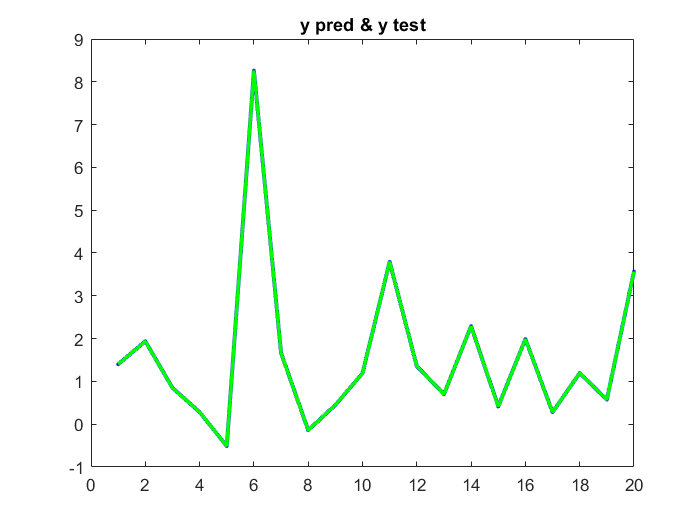

errbar = sqrt(diag(x_test * cov_teta_hat * x_test'));






plot(y_pred(1:20,:),'.-b','linewidth',2.3);
hold on
plot(y_test(1:20,:),'-g','linewidth',2);
title("y pred & y test");
 hold off 

 
%  subplot(subplot_rows, subplot_cols, i);
% plot(y_pred,'.-b','linewidth',2.3);
% hold on
% plot(y_test,'-g','linewidth',2);
% title("y pred & y test");
%  hold off 
%  
 
 
 

ghodrat_noise=errors.'*errors/(700-7);
deghat_takhmin=cov(theta);
deghat_model=MSE;

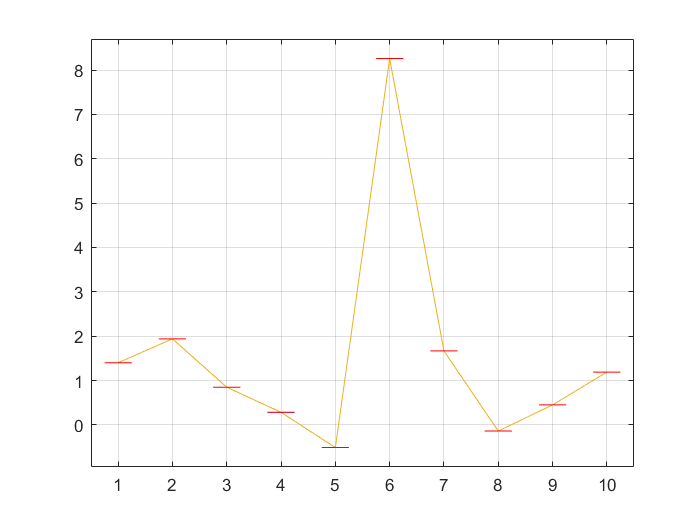

    
u1=1:1:10;
plot((y_pred(1:10,:)),'-');
hold on
plot((y_pred(1:10,:)+errbar(1:10,:)));
hold on
plot((y_pred(1:10,:)-errbar(1:10,:)));
grid

x=sort(u1).';
y=sort(y_pred(1:10,:)).';
data = [((y_pred(1:10,:))-errbar(1:10,:)).'; (y_pred(1:10,:)).'; ((y_pred(1:10,:))+errbar(1:10,:)).'];

% Add a box plot
boxplot(data, 'positions', x, 'widths', 0.5);
hold off

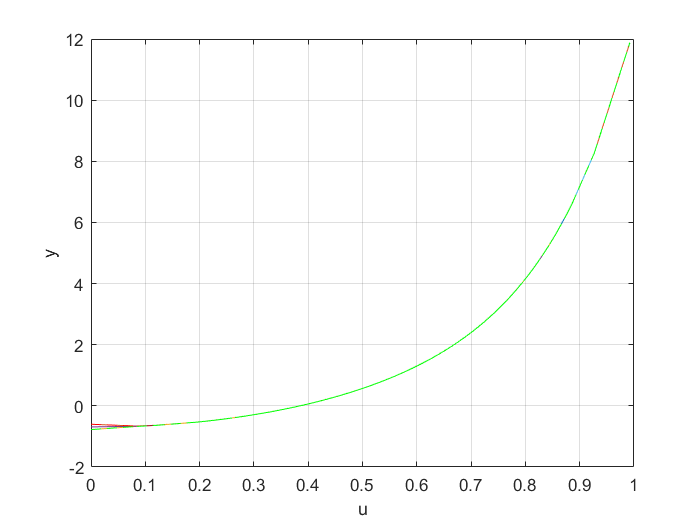

    upper_bound=y_pred + errbar;
    lower_bound=y_pred - errbar;
    
   [a_sorted, sort_idx] = sort(u);
b_sorted = y_pred(sort_idx);
c_sorted =upper_bound(sort_idx);
d_sorted =lower_bound(sort_idx);
% CI_low_sorted=CI_low(sort_idx)
% CI_high_sorted=CI_high(sort_idx)


plot(a_sorted, b_sorted, '-');
hold on;
plot(a_sorted, c_sorted, '-');
hold on
plot(a_sorted, d_sorted, '-');
hold on
% plot(a_sorted, CI_low_sorted, '-');
% hold on
% plot(a_sorted, CI_high_sorted, '-');
% hold on

for j = 1:length(a_sorted)-1
    x = [a_sorted(j), a_sorted(j+1)];
    y = [b_sorted(j), b_sorted(j+1)];
    plot(x, y);
    hold on
    xx = [a_sorted(j), a_sorted(j+1)];
    yy = [c_sorted(j), c_sorted(j+1)];
    plot(xx, yy, 'r--');
     hold on
    xxx = [a_sorted(j), a_sorted(j+1)];
    yyy = [d_sorted(j), d_sorted(j+1)];
    plot(xxx, yyy, 'g--');
%          hold on
%     xxxx = [a_sorted(j), a_sorted(j+1)];
%     yyyy = [CI_low_sorted(j), CI_low_sorted(j+1)];
%     plot(xxxx, yyyy, 'g--');
%          hold on
%     xxxxx = [a_sorted(j), a_sorted(j+1)];
%     yyyyy = [CI_high_sorted(j), CI_high_sorted(j+1)];
%     plot(xxxxx, yyyyy, 'g--');
end
    xlabel('u');
    ylabel('y');


    % Set subplot title

    hold off

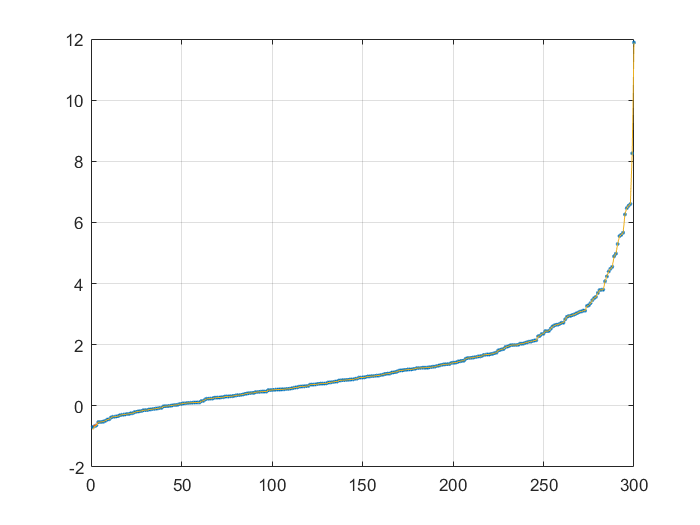

figure;
plot(sort(y_pred),'.');
hold on
plot(sort(y_pred+errbar));
hold on
plot(sort(y_pred-errbar));
grid

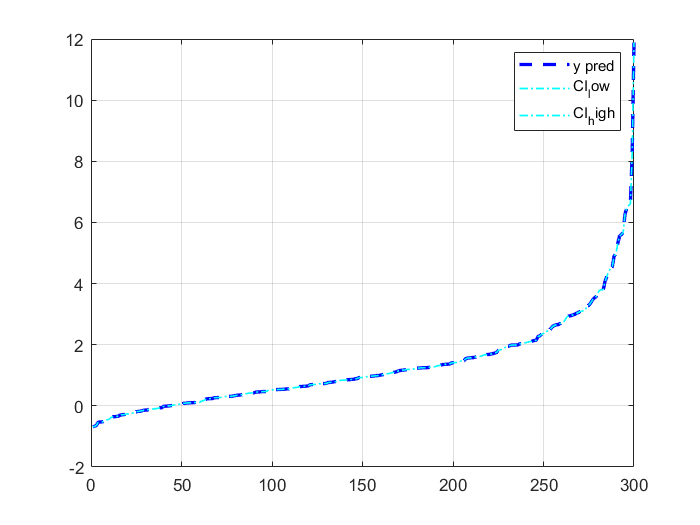

% Calculate the confidence interval
CI = 1.96 * std(errors) / sqrt(length(errors));
CI_low = y_pred - CI;
CI_high = y_pred + CI;

% Plot 
figure
plot(sort(y_pred), '--b', 'LineWidth', 2)
hold on
plot(sort(CI_low), '-.c', 'LineWidth', 1)
hold on
plot(sort(CI_high), '-.c', 'LineWidth', 1)
grid
legend('y pred', 'CI_low', 'CI_high')
hold off